## Non-linear MPC example

The following example considers the use of non-linear MPC to control the liquid level in a buffer tank. The details of the buffer tank model is given in the "Physical model" section below. The inlet flowrate and liquid level in the buffer tank is measured, and a hybrid extended Kalman filter is used to smooth the measured values. MPC is used to predict the outlet line fraction valve opening $f_x$to maintain the liquid level close to set-point.

clc; clear;

### Generate variable inlet flowrate

The first section of code will generate a stochastic inlet flowrate, which is modeled as an auto-regressive function:


$$F_{\mathrm{in}} \left(t_{k+1} \right)=\phi \;F_{\mathrm{in}} \left(t_k \right)+\left(1-\phi \;\right)\mu +\lambda \;\varepsilon$$


Where $\phi \;$is the autocorrelation coefficient, $\mu \;$is the mean inlet flowrate, $\lambda \;$is the standard deviation of the stochastic variation, and $\varepsilon$ is a random variable sampled from the standard normal distribution. 

The sampled values $F_{\textrm{in}} \left(t_k \right)$ are saved as a function of time using the "griddedInterpolant" function. 

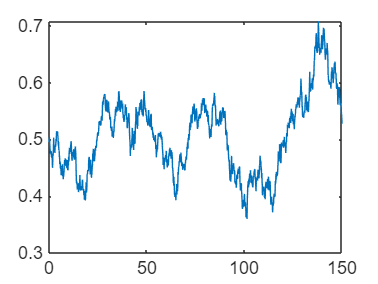

rng(1)
mu = 0.5;
phi = 0.999;
lambda = 0.0075;

N = 1500;
F_in = zeros(N,1); F_in(1) = mu;
for i = 2:N
    F_in(i) = phi*F_in(i-1) + (1-phi)*mu + lambda*randn;
end

t = linspace(0, 150, N);
u.F_in = griddedInterpolant(t, F_in);
plot(t, u.F_in(t))

### Parameters

Here we provide the model parameters ($A$ and $c_v$, see the "Physical Model" below), the Kalman filter process noise covariance $Q$ and measurement noise covariance $R$, and the MPC time-step between actions $t_{\textrm{step}}$ and prediction horizon $H$. In this example, the MPC time-step and the measurement time-step are both 1 minute.

We also provide the liquid-level set-point as a function of time

% Process parameters 
p.A = 10;   % m2, buffer tank cross-sectional area
p.cv = 0.5;   % m^2.5/min, valve constant

% Kalman filter parameters
%p.R = [0.025 0; 0 0.05]; % Measurement noise covariance 
p.R = 0.025;
p.Q = [0.001 0; 0 0.01]; % Process noise covariance 

% MPC parameters
p.tstep = 1;   % min, time steps between controller actions
p.H = 5;       % ~, number of time steps in controller prediction horizon
p.alpha = 0.1; % ~,m weighting parameter controlling the manipulated variable movement

% Set-point
xSP = @(t) 2 + 0.5*(t>20) - 1.2*(t>60); % m, liquid-level set-point

### Main script

#### Initialize

Here we do the following:

- We initialize the simulation by setting the true liquid level at time t = 0 equal to 2 m

- We generate noisy measurements using the "Measurement" function

- We initialize the state estimate by setting the estimate at t = 0 equal to the measured value and using an initial value for the state covariance matrix "P"

- Based on the initial data, we identifiy a trajectory of $f_x$ over the prediction horizon that minimizes our MPC objective function, then take the first element of this trajectory as the current fraction valve opening. Notice we use the bounds $0\le f_x \le 1$ in the optimization. We store the controller action as a function of time (even though it is constant) as the "ModelODE" function requires 

- We simulate the "ground truth" buffer tank over the first time interval, using the identified control action $f_x$

t = 0 : p.tstep : 150; % min, simulation time
opts = optimoptions('fmincon','Display','off'); % Set options for fmincon

% Initialize ground truth, measurements, and state estimates
sol.y = 2;                         % m, ground truth liquid level at t = 0 (anticipating the solution structure used in odextend)
y.h = []; y.F_in = [];             % ~, initialize the measurement structure
y = Measurement(sol, u, 0, p, y);  % Generate noisy measurements at t = 0
x = y;                             % At t = 0, set state estimates "x" equal to the measurement "y"
x.F_in = 0.5;
x.P{1} = [0.01 0; 0 0.1];          % State estimate covariance at t = 0

% Use fmincon to identify the vector of inputs "uv" corresponding to the
% fraction of valve openings over the prediction , with 0 <= fx <= 1
[u_trajectory,~,exitflag(1), output{1}] = ...
    fmincon(@(uv) MPC_ObjectiveFunction(t(1), uv, x, p, xSP), 0.5*ones(p.H,1), [], [], [], [], zeros(p.H,1), ones(p.H,1), [], opts);

Error using fmincon (line 633)
Optimization Toolbox must be installed to call fmincon.


% Store the selected action in a vector
fx_plot = u_trajectory(1);

% Store the selected action as a function of time, as the model function
% require "u" as a function of time
u.fx = @(t) fx_plot;


% Simulate the ground truth over the first time interval
sol = ode45(@(t, x) ProcessODE(t, x, u, p), [t(1) t(2)], sol.y);

#### Loop for all time-steps

Following the initialization, the following steps are iterated:

- Given the current ground truth, generate noisy measurements

- Use the Kalman filter to generate new state estimates

- Use MPC to select the next controller action. We store the selected action as a function of time using "griddedInterpolant" and the "previous" method of interpolation, which ensures "u" always takes on the value of the most recently selected action.

- Simulate the "ground truth" over the next time interval

This is repeated until the end of the simulation time

for i = 2:length(t)-1
    y = Measurement(sol, u, t(i), p, y);         % Measurements updated at t(i) using ground truth "sol"
    x = KalmanFilter(y, x, u, p, [t(i-1) t(i)]); % State estimates at t(i)
    
    % Find the optimal trajectory over the time horizon, select the
    % controller action, and store the selected action to plot later
    [u_trajectory,~, exitflag(i), output{i}] = ...
       fmincon(@(uv) MPC_ObjectiveFunction(t(i), uv, x, p, xSP), u_trajectory, [], [], [], [], zeros(p.H,1), ones(p.H,1), [], opts);
    fx_plot(end+1) = u_trajectory(1);
    u.fx = griddedInterpolant(t(1:i), fx_plot, 'previous');
    
    % Simulate the ground truth over the next time interval
    sol = odextend(sol, @(t, x) ProcessODE(t, x, u, p), t(i+1));
end

% Final measurements and state estimates
y = Measurement(sol, u, t(end), p, y);    % Measurements at t = 0
x = KalmanFilter(y, x, u, p, [t(i) t(end)]);

#### Plot results

plot(sol.x, sol.y, t, y.h, '.', t, x.h, t, xSP(t), 'k--'); 
ylabel('Liquid level (m)'); xlabel('Time (min)')
legend('Ground truth', 'Measurement','State estimate')

%plot(sol.x, u.F_in(sol.x), t, y.F_in, '.', t, x.F_in); 
plot(sol.x, u.F_in(sol.x), t, x.F_in); 
ylabel('Inlet flowrate (m^3/min)'); xlabel('Time (min)')
legend('Ground truth', 'State estimate')

stairs(t(2:end), fx_plot); 
ylabel('Valve fraction'); xlabel('Time (min)')

## Process model

The buffer tank can be described using the following ODE:


$$\frac{dh}{dt}=\frac{1}{A}\left(F_{\mathrm{in}} -f_x c_v \sqrt{\;h}\right)$$


Where $h$ is the liquid level, $A$ is the tank cross-sectional area, $F_{\textrm{in}}$ is the inlet flowrate, $f_x \in \left\lbrack 0,1\right\rbrack$ is the fraction valve opening, and $c_{v\;}$ is the valve flow constant. The inlet flowrate and fraction valve opening are functions contained in the "u" structure, and the parameters in the "p" structure. The "ProcessODE" represents the physical process which we use to simulate the plant. It is different from "ModelODE" introduced later, which represents our model of the process.

function dhdt = ProcessODE(t, h, u, p)
    dhdt = ( u.F_in(t) - u.fx(t)*p.cv*sqrt(h) ) / p.A;
end

## Measurement

The measurement function simply provides a noisy measurement based on the ground truth:

function y = Measurement(sol, u, t, p, y)
    y.h(end+1) = sol.y(end) + p.R(1,1)*randn;
    %y.F_in(end+1) = u.F_in(t) + p.R(2,2)*randn;
end

## Kalman filter

We implement a hybrid extended Kalman filter, which is described by the following:


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=f\left(x,u\right)+w\\
y=h\left(x,u\right)+v
\end{array}$$



$$\frac{\textrm{dP}}{\textrm{dt}}=\textrm{AP}+{\textrm{PA}}^T +Q$$


Where the process noise $w$ has covariance $Q$ and the measurement noise $v$ has covariance $R$. The matrix $A$ represents the Jacobian of the time derivative with elements $A_{\textrm{ij}} =\frac{\partial f_i }{\partial x_{j\;} }$.

Using the posterior state estimate ${\hat{x\;} }^+ \left(t_k \right)$ and covariance estimate $P^+ \left(t_k \right)$ we can estimate the prior of each at time step $t_{k+1}$ (i.e., ${\hat{x\;} }^- \left(t_{k+1} \right)$ and covariance estimate $P^- \left(t_{k+1} \right)$) by integrating the equations above. The posterior is then obtained using the Kalman update:


$$K=P^- H^T {\left(HP^- H^T +R\right)}^{-1}$$
 


$${\hat{x\;} }^+ ={\hat{x} }^- +K\left(y-h\left({\hat{x\;} }^- ,u\right)\right)$$



$$P^+ =\left(I-\textrm{KH}\right)P^-$$


The matrix $H$ represents the Jacobian of the measurement function with elements $H_{\textrm{ij}} =\frac{\partial h_i }{\partial x_{j\;} }$. In our case, the measurements measure the states directly, so $y=h\left(x,u\right)=x$. This results in $H=I$

function x = KalmanFilter(y, x, u, p, t)
    % Create a vector containing only latest measurement
    %yv = [y.h(end); y.F_in(end)];           
    yv = y.h(end);           

    % Integrate the states and covariance matrix to find the prior at the next timestep
    x0 = [x.h(end); x.F_in(end); reshape(x.P{end}, 4, 1)];
    [~, x_integrate] = ode45(@(t, x) KalmanODE(t, x, u, p), t, x0);
    x_prior = x_integrate(end, 1:2)';
    P_prior = reshape(x_integrate(end, 3:end), 2, 2);
    
    % Calculate the Kalman gain
    %H = eye(2);
    H = [1 0];
    K = P_prior*H'*inv(H*P_prior*H' + p.R);
    
    % Find the posterior state estimate
    x_posterior = x_prior + K*(yv - H*x_prior);
    P_posterior = (eye(2) - K*H)*P_prior;

    % Append the posterior to the state estimate structure
    x.h(end+1) = x_posterior(1);
    x.F_in(end+1) = x_posterior(2);
    x.P{end+1} = P_posterior;
end

Estimating the Kalman prior requires integrating a model of the system. This model must include the unmeasured inlet flowrate as a state variable, which we assume stays constant except for (large) process noise:


$$\begin{array}{l}
\frac{\textrm{dh}}{\textrm{dt}}=\frac{1}{A}\left(F_{\textrm{in}\;} -f_x c_v \sqrt{h}\right)+w_h \\
\frac{{\textrm{dF}}_{\textrm{in}} }{\textrm{dt}}=0+w_{F_{\textrm{in}} } 
\end{array}$$


The function below calculates the time derivative of the states using the model equations, which will in turn be numerically integrated to give the prior state estimates. The "ModelODE" function is shared between the Kalman filter and the MPC.

function [dxdt, x] = ModelODE(t, xv, u, p)
    % Convert vector of state variables to a structure
    x.h = xv(1);
    x.F_in = xv(2);
    
    % Calculate the time derivative of the state variables
    ddt.h = ( x.F_in - u.fx(t)*p.cv*sqrt(x.h) ) / p.A;
    ddt.F_in = 0;
    dxdt = [ddt.h; ddt.F_in];
end

The Kalman filter requires a prior estimate on the covariance matrix as well, which may also be determined by numerically integrating $\frac{\textrm{dP}}{\textrm{dt}}$:


$$\begin{array}{l}
\frac{dP}{dt}=AP+{PA}^T +Q\\
A=\left\lbrack \begin{array}{cc}
\frac{\partial f_1 }{\partial h} & \frac{\partial f_1 }{\partial F_{\mathrm{in}} }\\
\frac{\partial f_2 }{\partial h} & \frac{\partial f_2 }{\partial F_{\mathrm{in}} }
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\frac{f_x c_v }{2A\sqrt{h}} & \frac{1}{A}\\
0 & 0
\end{array}\right\rbrack 
\end{array}$$


The function below first calculates the derivative of the states, then appends the derivative of the covariance matrix for numerical integration. While the MPC does rely on "ModelODE", it does not use "KalmanODE" to estimate the state covariances (some forms of robust MPC might do so).

function dxdt = KalmanODE(t, xv, u, p)
    [dxdt, x]= ModelODE(t, xv, u, p);
    x.P = reshape(xv(3:end), 2, 2);
    
    % Calculate the time derivative of the covariance matrix, which relies
    % on the Jacobian matrix A as described above
    A = [-u.fx(t)*p.cv/sqrt(x.h)/p.A/2  1/p.A; 0 0];
    ddt.P = A*x.P + x.P*A' + p.Q;
    
    dxdt = [dxdt; reshape(ddt.P, 4, 1)];
end

## MPC

The model predictive controller must predict the response of the system given the current state estimate and a set trajectory of control inputs ${\mathbf{u}}_{\textrm{fx}} =\left\lbrack u_{\textrm{fx}} \left(t_k \right),u_{\textrm{fx}} \left(t_{k+1} \right),\ldotp \ldotp \ldotp u_{\textrm{fx}} \left(t_{k+H} \right)\right\rbrack$ over a prediction horizon $t_k \le t\le t_{k+H}$. It must then select the trajectory ${\mathbf{u}}_{\textrm{fx}}$ that minizes the MPC objective function $J$:


$$J=\sum_{l=0}^{H-1} {\left(x\left(t_{k+l} \right)-x^{\textrm{SP}} \left(t_{k+l} \right)\right)}^2 +\alpha \;\sum_{l=1}^{H-1} {\left(u\left(t_{k+l} \right)-u\left(t_{k+l-1} \right)\right)}^2$$


Where $\alpha \;$ is a parameter that controls the penalty on the controller action $\Delta \;u$

function J = MPC_ObjectiveFunction(tStart, u_fx, x, p, xSP)
    % Define the time horizon and set the inlet flowrate and liquid level
    % equal to the current state estimate
    t = tStart + (0 : p.tstep : p.tstep*(p.H-1));
    x0 = [x.h(end); x.F_in(end)];
    
    % Given a trajectory u_fx, define the controller input as a function of
    % time using the "griddedInterpolant". 
    u.fx = griddedInterpolant(t, u_fx, 'previous');
    
    % Predict the state response given the controller input
    [~, x_response] = ode45(@(t, x) ModelODE(t, x, u, p), t, x0);
    x.h = x_response(:,1)';

    % Calculate the MPC objective function
    J = sum( (xSP(t) - x.h).^2 ) + p.alpha*sum( (u_fx(2:end) - u_fx(1:end-1)).^2);
end

The MPC model used for prediction is the same as that used for the Kalman filter, "ModelODE".